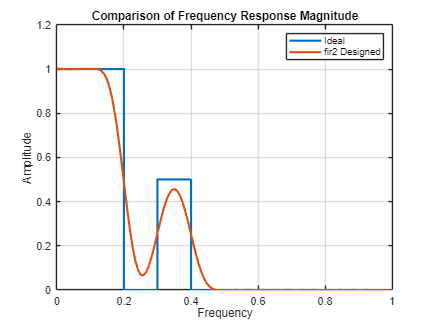

% FIR Filter Design and Frequency Response Analysis
% --------------------------------------------------
% This script designs a Finite Impulse Response (FIR) filter using the fir2 
% function, which allows for the specification of an arbitrary piecewise 
% linear frequency response. It then plots the designed filter's frequency 
% response alongside the ideal frequency response for comparison.

% Define the filter order
n = 51;

% Define the frequency and magnitude vectors
f = [0 0.2 0.2 0.3 0.3 0.4 0.4 1];
m = [1 1 0 0 0.5 0.5 0 0];

% Design the FIR filter using the fir2 function
b = fir2(n-1, f, m);

% Compute the frequency response of the designed filter
[h, w] = freqz(b, 1, 128);

% Plot the ideal and designed frequency responses
figure;
plot(f, m, 'LineWidth', 2);          % Plot the ideal response
hold on;
plot(w/pi, abs(h), 'LineWidth', 2);  % Plot the designed response
grid on;

% Add legend and labels
legend('Ideal', 'fir2 Designed');
title('Comparison of Frequency Response Magnitude');
xlabel('Frequency');
ylabel('Amplitude');